load('cluster_data.mat');
k = 4; 
X1 = dataA_X;
X2 = dataB_X;
X3 = dataC_X;
[d,n] = size(X1);

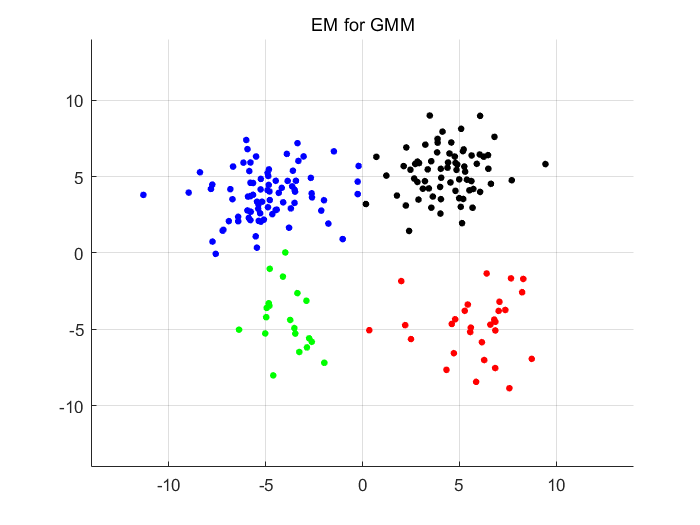

init_miu1 = zeros(d,k);
init_miu1(:,1)=[10,-10];
init_miu1(:,2)=[-10,-10];
init_miu1(:,3)=[-10,10];
init_miu1(:,4)=[10,10];

init_pi1 = zeros(1,k); 
init_sigma1 = zeros(d,d,k); 

a=repmat(sum(X1'.*X1',2),1,k);
b=repmat(sum(init_miu1'.*init_miu1',2)',n,1);
c=2*X1'* init_miu1;
distance = a + b - c;

[~,labels] = min(distance,[],2);

for j=1:k
    Xj = X1(:,labels == j);
    init_pi1(j) = size(Xj,1) / n;
    cc = cov(Xj');
    init_sigma1(:,:,j) = cc;
end

[miu_a, label_a] = EM(X1,k,init_miu1,init_sigma1,init_pi1);
plotClustering(X1,label_a);
title('EM for GMM');

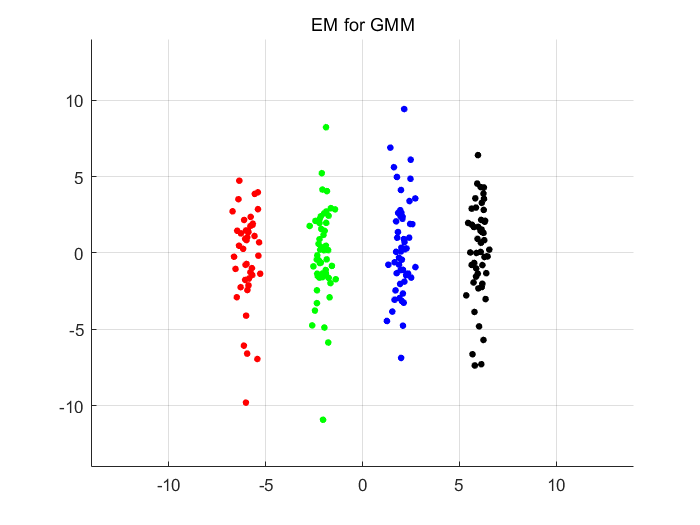

init_miu2 = zeros(d,k);
init_miu2(:,1)=[-5,0];
init_miu2(:,2)=[-1,0];
init_miu2(:,3)=[1,0];
init_miu2(:,4)=[5,0];

init_pi2 = zeros(1,k); 
init_sigma2 = zeros(d,d,k); 

a=repmat(sum(X2'.*X2',2),1,k);
b=repmat(sum(init_miu2'.*init_miu2',2)',n,1);
c=2*X2'* init_miu2;
distance = a + b - c;

[~,labels] = min(distance,[],2);

for j=1:k
    Xj = X2(:,labels == j);
    init_pi2(j) = size(Xj,1) / n;
    cc = cov(Xj');
    init_sigma2(:,:,j) = cc;
end
[miu_b, label_b] = EM(X2,k,init_miu2,init_sigma2,init_pi2);
plotClustering(X2,label_b);
title('EM for GMM');

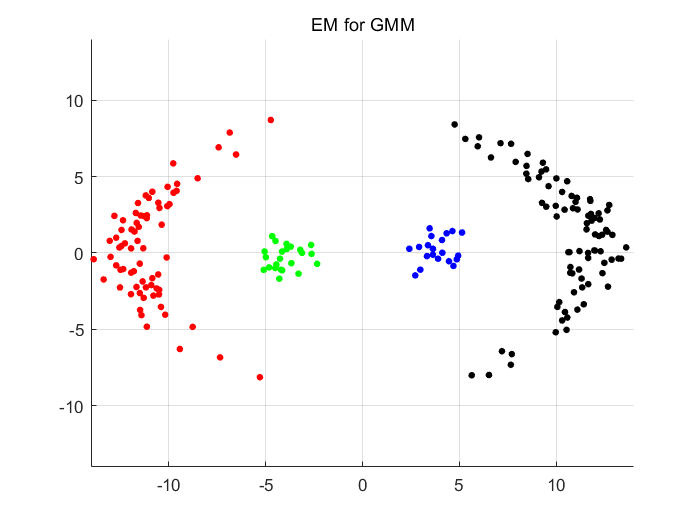

init_miu3 = zeros(d,k);
init_miu3(:,1)=[-10,0];
init_miu3(:,2)=[-1,0];
init_miu3(:,3)=[1,0];
init_miu3(:,4)=[10,0];
init_pi3 = zeros(1,k); 
init_sigma3 = zeros(d,d,k); 

a=repmat(sum(X3'.*X3',2),1,k);
b=repmat(sum(init_miu3'.*init_miu3',2)',n,1);
c=2*X3'* init_miu3;
distance = a + b - c;

[~,labels] = min(distance,[],2);

for j=1:k
    Xj = X3(:,labels == j);
    init_pi3(j) = size(Xj,1) / n;
    cc = cov(Xj');
    init_sigma3(:,:,j) = cc;
end
[miu_c, label_c] = EM(X3,k,init_miu3,init_sigma3,init_pi3);
plotClustering(X3,label_c);
title('EM for GMM');